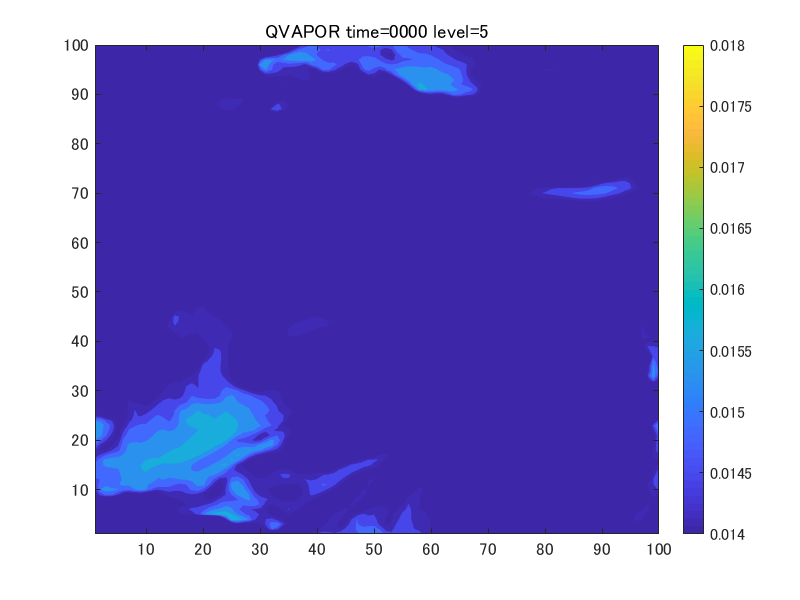

%---------------------
% plot animination for a level of 3-D variable
%---------------------
close all
clear
%---setting
expri='test25';
year='2007'; mon='06'; date=1;
hr=1:24; minu='00';    zi=5;
n=0;

varinam='QVAPOR';
filename=[expri,'_gif_',varinam,'_lev',num2str(zi),'.gif'];
h=figure('Position',[100 100 800 600]);

for ti=hr
   if ti>=48
       s_date=num2str(date+2,'%2.2d');
       s_hr=num2str(ti-48,'%2.2d');
   elseif ti>=24
       s_date=num2str(date+1,'%2.2d');
       s_hr=num2str(ti-24,'%2.2d');
   else
       s_date=num2str(date,'%2.2d');
       s_hr=num2str(ti,'%2.2d');
   end   
   
   infile = [expri,'/wrfout_d01_',year,'-',mon,'-',s_date,'_',s_hr,'%3A',minu,'%3A00'];
   %infile = ['wrfout_d02_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
   qv = ncread(infile,varinam);  
   %qv = ncread(infile,'QVAPOR');   
   %u = ncread(infile,'U');
   %v = ncread(infile,'V');
   %t = ncread(infile,'T'); t=t+300;
   %ph = ncread(infile,'PH'); phb = ncread(infile,'PHB');
   %z=(ph+phb)./9.81; 
   %x = double(ncread(infile,'XLONG',[1 1 1],[Inf Inf 1]));
   %y = double(ncread(infile,'XLAT',[1 1 1],[Inf Inf 1]));
   %ti=20; 
   %hgt= ncread(infile,'HGT');
   %rc = ncread(infile,'RAINC');
   %rsh = ncread(infile,'RAINSH');
   %rnc = ncread(infile,'RAINNC');
   %rain=rc+rsh+rnc;

%---plot different variables
% figure('Position',[100 100 600 400])
%   contourf(u(:,:,3)',20,'linestyle','none')
%   title(['u time=',s_hr,minu,' level=',num2str(zi)],'FontSize',15)
%   colorbar
% figure
%   contourf(v(:,:,zi,ti)',20,'linestyle','none')
%   title([expri,' v, ti=',num2str(ti),', zi=',num2str(zi)],'FontSize',15)
%   colorbar
%figure
  contourf(qv(:,:,zi)',20,'linestyle','none')
  title([varinam,' time=',s_hr,minu,' level=',num2str(zi)],'FontSize',15)
  colorbar;  caxis([0.014 0.018])
  set(gca,'fontsize',13)
  
  n=n+1;
  frame=getframe(h);  im=frame2im(frame);
  [imind, cm]=rgb2ind(im,256);
  if n == 1 
    imwrite(imind,cm,filename,'gif','Loopcount',Inf,'DelayTime',0.2); 
  else 
    imwrite(imind,cm,filename,'gif','WriteMode','append'); 
  end   

% figure
%   contourf(rain',20,'linestyle','none')
%   title(['Preci. time=',s_hr,minu,],'FontSize',15)
%   colorbar
% figure
%   contourf(t(:,:,zi)',20,'linestyle','none')
%   title(['potential temp time=',s_hr,minu,' level=',num2str(zi)],'FontSize',15)
%   colorbar  
% %caxis([-30 30])
% figure
%   contourf((z(:,:,zi,ti)+z(:,:,zi+1,ti))*0.5,20,'linestyle','none')
%   title([expri,' geopotential height, ti=',num2str(ti),', zi=',num2str(zi)],'FontSize',15)
%   colorbar  
% figure('Position',[100 100 600 400])
%   contourf(rain(:,:,ti)',20,'linestyle','none')
%   title(['rain, ti=',num2str(ti),', zi=',num2str(zi)],'FontSize',15)
%   colorbar
end

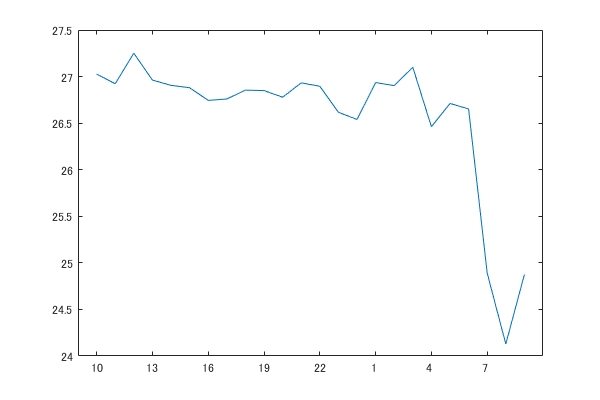

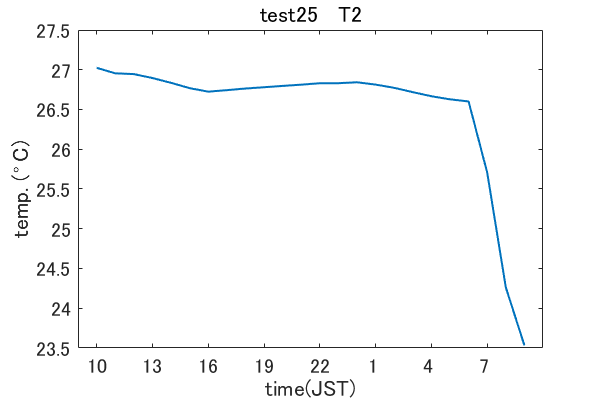

close all

clear
%---setting
expri='test14';
year='2019'; mon='08'; date='18';
hr=12:18; minu='00'; 
n=0;

filename=[expri,'_gif_t2.gif'];
h=figure('Position',[100 100 600 400]);

for ti=hr
    s_hr=num2str(ti,'%2.2d');
   infile = [expri,'/wrfout_d01_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
   t2 = ncread(infile,'T2');   
  contourf(t2(:,:)',20,'linestyle','none')
  title(['T2 time=',s_hr,minu],'FontSize',15)
  colorbar;  %caxis([27+273 27.15+273])
  set(gca,'fontsize',13)
  
  n=n+1;
  frame=getframe(h);  im=frame2im(frame);
  [imind, cm]=rgb2ind(im,256);
  if n == 1 
    imwrite(imind,cm,filename,'gif','Loopcount',Inf,'DelayTime',0.2); 
  else 
    imwrite(imind,cm,filename,'gif','WriteMode','append'); 
  end   

end


clear
close all

expri='test14';
year='2019'; mon='08'; date='18';
hr=12:18; minu='00'; zi=3;
n=0;

% varinam='qv';
filename=[expri,'_gif_qv_lev',num2str(zi),'.gif'];
h=figure('Position',[100 100 600 400]);

% variplot=double(qv);

for ti=hr
   s_hr=num2str(ti,'%2.2d');
   infile = [expri,'/wrfout_d01_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
   qv = ncread(infile,'QVAPOR');   
   
  contourf(qv(:,:,zi)',20,'linestyle','none')
  title(['qv time=',s_hr,minu,' level=',num2str(zi)],'FontSize',15)
  colorbar;  caxis([0.0108 0.011])
  set(gca,'fontsize',13)
  
  n=n+1;
  frame=getframe(h);  im=frame2im(frame);
  [imind, cm]=rgb2ind(im,256);
  if n == 1 
    imwrite(imind,cm,filename,'gif','Loopcount',Inf,'DelayTime',0.2); 
  else 
    imwrite(imind,cm,filename,'gif','WriteMode','append'); 
  end   
end
